%Flight Conditions
V = 350 %kts 

V = 350

h = 25000 %ft

h = 25000

DynVisc = 3.2166*10^(-7); %Slug/ft-s CHANGES WITH ALT
W = 158356*0.946

W = 1.4980e+05


[TempRat, PresRat, DensRat, SpeedSound] = ISA(h);
V=V*1.688

V = 590.8000

M = V/SpeedSound

M = 0.5817


%Airfoil Parameters
Cla = 2*pi

Cla = 6.2832

Tmax = 0.15

Tmax = 0.1500

LocMaxT = 0.4

LocMaxT = 0.4000

PerLamFlow = 0.1

PerLamFlow = 0.1000

CLDMin = 0.1

CLDMin = 0.1000


%Planform Parameters
S = 1693; %ft^2
AR = 8.23

AR = 8.2300

%AR2 = 5.23
%b2=100
TaperRatio = 0.4;
b = 118

b = 118

Q = 1.01

Q = 1.0100

SweepQuartC = 0;

%Fuselage Parameters
Df = 15.5; %ft
LNose = 16; %ft
LMid = 44; %ft
LTail = 37.3 %ft

LTail = 37.3000

DBase = 4 %ft

DBase = 4

ABase = pi*DBase^2/4

ABase = 12.5664

UpsweepAngle = atan((Df/2-DBase/2)/LTail); %rad

%Vertical Tail Parameters NOTE: Half Wing
Sv = 300*2; %ft^2
ARv = 7.05;
TaperRatiov = 0.55;
bv = sqrt(ARv*Sv);
QVt = 1.05;
LocMaxTv = 0.35;
Tmaxv = 0.12

Tmaxv = 0.1200


%Horizontal Tail Parameters
Sh = 400; %ft^2
ARh = 6.42;
TaperRatioh = 0.35;
bh = sqrt(ARh*Sh);
QHt = 1.05;
LocMaxTh = 0.35;
Tmaxh = 0.12

Tmaxh = 0.1200


%Nacelle Parameters
LNacelle = 78/12;
DNacelle = 34/12;

%Induced Drag Factor

Ne = 0; %Num of engines ON TOP of Wing
TaperFunc = 0.005*(1+1.5*(TaperRatio-0.6)^2)

TaperFunc = 0.0053

K = (1+(0.142+TaperFunc*AR*(10*Tmax)^(0.33))/(cosd(SweepQuartC)^2)+(0.1*(3*Ne+1))/((4+AR)^0.8))*(1+0.12*M^6)/(pi*AR)

K = 0.0468

e = 1/(K*AR*pi)

e = 0.8258


[CDoWing] = WingZeroLiftDrag(V,Q,TaperRatio,DynVisc,0,S,AR,b,h,LocMaxT,Df,PerLamFlow,Tmax);

V = 997.2704

M = 0.9820

Cr = 20.4964

Cmac = 15.2259

Ymac = 25.2857

SweepMaxT = -1.7896

Cf = 18.8810

Sexp = 1.3878e+03

Re = 8.4781e+07

SweepMaxT = -1.7896

FF = 1.7035

Swet = 2.8520e+03

CDo = 0.0062


[CDoHt] = WingZeroLiftDrag(V,QHt,TaperRatioh,DynVisc,0,Sh,ARh,bh,h,LocMaxTh,0,PerLamFlow,Tmaxh);

V = 997.2704

M = 0.9820

Cr = 11.6939

Cmac = 8.5033

Ymac = 10.6356

SweepMaxT = -1.7183

Cf = 11.6939

Sexp = 400

Re = 4.7348e+07

SweepMaxT = -1.7183

FF = 1.6379

Swet = 815.7600

CDo = 0.0082


CDoHt = CDoHt*Sh/S

CDoHt = 0.0019


[CDoVt] = WingZeroLiftDrag(V,QVt,TaperRatiov,DynVisc,0,Sv,ARv,bv,h,LocMaxTv,0,PerLamFlow,Tmaxv);

V = 997.2704

M = 0.9820

Cr = 11.9036

Cmac = 9.4845

Ymac = 14.6861

SweepMaxT = -0.9437

Cf = 11.9036

Sexp = 600

Re = 5.2812e+07

SweepMaxT = -0.9437

FF = 1.6380

Swet = 1.2236e+03

CDo = 0.0080


CDoVt = CDoVt*Sv/S/2

CDoVt = 0.0014


[CDoFuse] = ParaDragFuse(h,V,LMid,LNose,LTail,Df,DynVisc,S)

FF = 1.2582

CDoFuse = 0.0054


[CDoNacelle] = 8*ParaDragNacelle(h,V,LNacelle,DNacelle,DynVisc,S)

CDoNacelle = 0.0010


UpSweepDrag = 3.83*UpsweepAngle^2.5*pi*Df^2/4/S

UpSweepDrag = 0.0039


CDoCamber = e/(1-e)*K*CLDMin^2

CDoCamber = 0.0022


BaseDrag = (0.1+0.1222*M^8)*ABase/S

BaseDrag = 7.5415e-04


CDoTotal = CDoWing + CDoHt + CDoVt + CDoFuse + UpSweepDrag + BaseDrag + CDoNacelle + CDoCamber

CDoTotal = 0.0228





CL = -0.5:0.01:1.5

CL =    -0.5000   -0.4900   -0.4800   -0.4700   -0.4600   -0.4500   -0.4400   -0.4300   -0.4200   -0.4100   -0.4000   -0.3900   -0.3800   -0.3700   -0.3600   -0.3500   -0.3400   -0.3300   -0.3200   -0.3100   -0.3000   -0.2900   -0.2800   -0.2700   -0.2600   -0.2500   -0.2400   -0.2300   -0.2200   -0.2100   -0.2000   -0.1900   -0.1800   -0.1700   -0.1600   -0.1500   -0.1400   -0.1300   -0.1200   -0.1100   -0.1000   -0.0900   -0.0800   -0.0700   -0.0600   -0.0500   -0.0400   -0.0300   -0.0200   -0.0100



LDMax = 0;

for x=1:201
    
   CD(x) = CDoTotal + K*CL(x)^2;
   
   if CL(x)/CD(x)>LDMax
       
       LDMax = CL(x)/CD(x)
       
   end
   
end

LDMax = 0.4378

LDMax = 0.8751

LDMax = 1.3112

LDMax = 1.7458

LDMax = 2.1783

LDMax = 2.6081

LDMax = 3.0347

LDMax = 3.4577

LDMax = 3.8766

LDMax = 4.2909

LDMax = 4.7001

LDMax = 5.1039

LDMax = 5.5019

LDMax = 5.8935

LDMax = 6.2786

LDMax = 6.6567

LDMax = 7.0276

LDMax = 7.3909

LDMax = 7.7464

LDMax = 8.0938

LDMax = 8.4330

LDMax = 8.7637

LDMax = 9.0857

LDMax = 9.3990

LDMax = 9.7034

LDMax = 9.9989

LDMax = 10.2853

LDMax = 10.5626

LDMax = 10.8307

LDMax = 11.0897

LDMax = 11.3396

LDMax = 11.5804

LDMax = 11.8122

LDMax = 12.0350

LDMax = 12.2488

LDMax = 12.4538

LDMax = 12.6502

LDMax = 12.8379

LDMax = 13.0171

LDMax = 13.1880

LDMax = 13.3507

LDMax = 13.5054

LDMax = 13.6522

LDMax = 13.7913

LDMax = 13.9228

LDMax = 14.0470

LDMax = 14.1639

LDMax = 14.2739

LDMax = 14.3770

LDMax = 14.4735

LDMax = 14.5636

LDMax = 14.6474

LDMax = 14.7251

LDMax = 14.7969

LDMax = 14.8630

LDMax = 14.9235

LDMax = 14.9788

LDMax = 15.0288

LDMax = 15.0739

LDMax = 15.1142

LDMax = 15.1498

LDMax = 15.1810

LDMax = 15.2078

LDMax = 15.2305

LDMax = 15.2493

LDMax = 15.2641

LDMax = 15.2753

LDMax = 15.2830

LDMax = 15.2873

LDMax = 15.2884

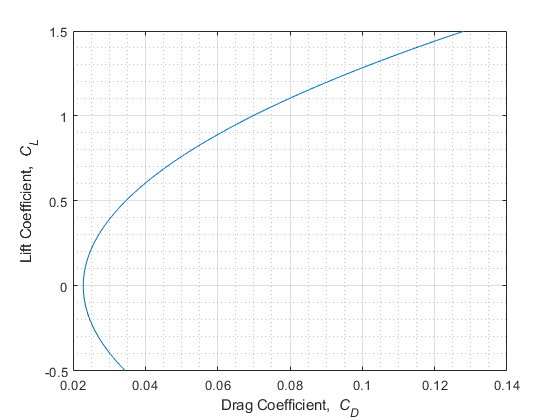


% K2 = 1/(0.987*pi*AR)
% 
% LDMax2 = 0;
% 
% for x=1:201
%     
%    CD2(x) = CDoTotal2 + K2*CL(x)^2;
%    
%    if CL(x)/CD(x)>LDMax2
%        
%        LDMax2 = CL(x)/CD2(x)
%        
%    end
%    
% end

plot (CD,CL)

xlabel('Drag Coefficient, {\it C_{D}}')
ylabel('Lift Coefficient, {\it C_{L}}')
grid on
grid minor


LDMax

LDMax = 15.2884